# Test Case - Power Split Geartrain

mdl = "PowerSplitGeartrain_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
PowerSplitGeartrain_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/MG2 clutch", Before="0");
simIn = setBlockParameter(simIn, mdl+"/MG2 clutch", Time="1");
simIn = setBlockParameter(simIn, mdl+"/MG2 clutch", After="0");

simIn = setBlockParameter(simIn, mdl+"/MG2 speed", Before="0");
simIn = setBlockParameter(simIn, mdl+"/MG2 speed", Time="1");
simIn = setBlockParameter(simIn, mdl+"/MG2 speed", After="0");

simIn = setBlockParameter(simIn, mdl+"/MG1 clutch", Before="0");
simIn = setBlockParameter(simIn, mdl+"/MG1 clutch", Time="1");
simIn = setBlockParameter(simIn, mdl+"/MG1 clutch", After="0");

simIn = setBlockParameter(simIn, mdl+"/MG1 speed", Before="0");
simIn = setBlockParameter(simIn, mdl+"/MG1 speed", Time="1");
simIn = setBlockParameter(simIn, mdl+"/MG1 speed", After="0");

simIn = setBlockParameter(simIn, mdl+"/Axle clutch", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Axle clutch", After="0");

simIn = setBlockParameter(simIn, mdl+"/Vehicle speed kph", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Vehicle speed kph", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Vehicle speed kph", After="0");

simIn = setBlockParameter(simIn, mdl+"/Engine clutch", Before="1");
simIn = setBlockParameter(simIn, mdl+"/Engine clutch", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Engine clutch", After="1");

simIn = setBlockParameter(simIn, mdl+"/Engine speed", Before="4000");
simIn = setBlockParameter(simIn, mdl+"/Engine speed", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Engine speed", After="4000");

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "100");

% Run simulation
simOut = sim(simIn);

## Visualize Simulation Result

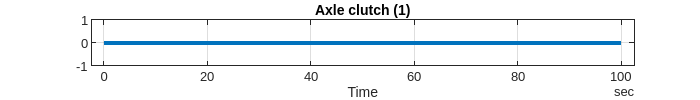

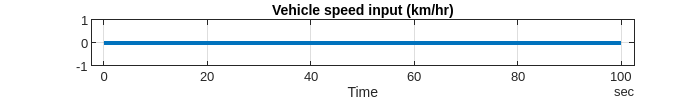

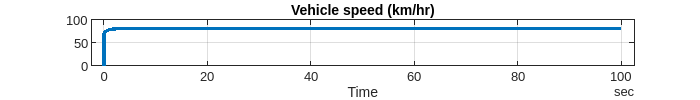

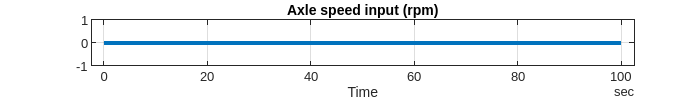

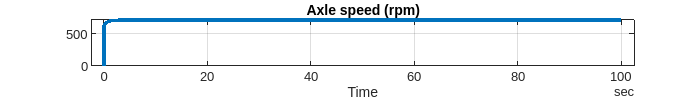

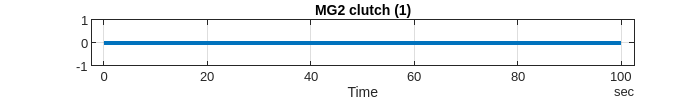

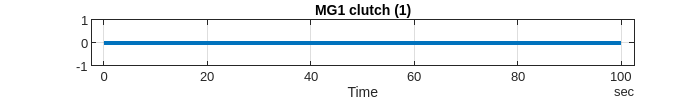

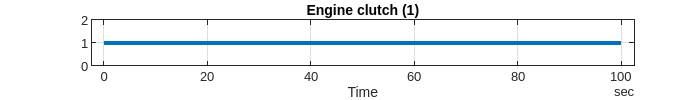

simData = extractTimetable(simOut.logsout);

PowerSplitGeartrain_Component_plotResults(SimData = simData, FigureHeight = 100);

*Copyright 2021-2022 The Mathworks, Inc.*